## Tilt step response - Real system test

clear
clc

% Loading and preping data from raw_tilt_values
error = load('raw_tilt_values.txt');
Fs = 1000; Ts = 1/Fs;
n = min(length(error), 2700);
t_meas = (0:n-1)' * Ts;
y = 1 - error(1:n) / max(error);

%%% Setting up figure %%%
figure;
% plot(t_meas, y, 'bo', 'MarkerSize', 4); hold on;  % Plot raw normalized data points

% Fit polynomial with 17 degree
deg = 17;
p = polyfit(t_meas, y, deg);

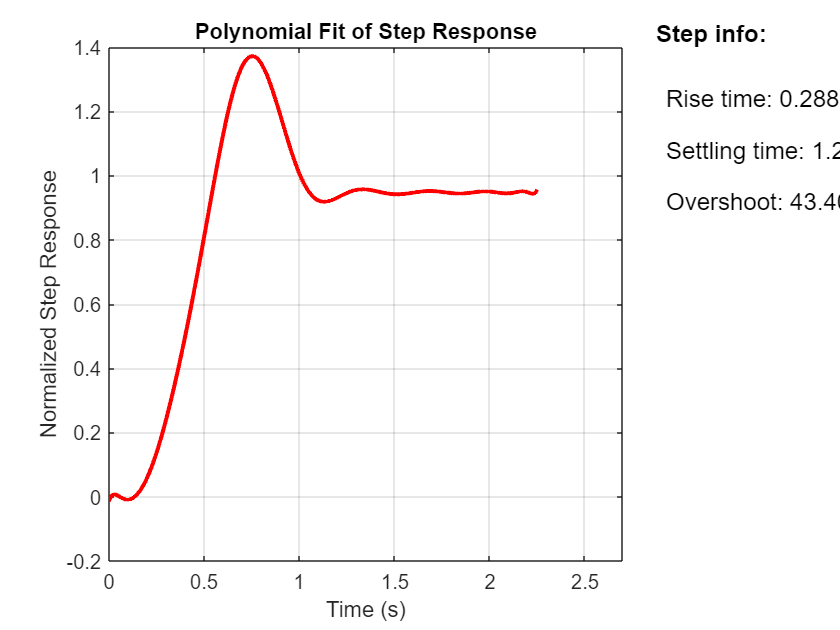


% Evaluate polynomial only in data range
t_sim = linspace(t_meas(1), t_meas(end), 1000)';
y_poly = polyval(p, t_sim);

% Approximate final value
final_val = y_poly(end);

% Rise time: time from 10% to 90% of final value
idx_10 = find(y_poly >= 0.1 * final_val, 1, 'first');
idx_90 = find(y_poly >= 0.9 * final_val, 1, 'first');
rise_time = t_sim(idx_90) - t_sim(idx_10);

% Settling time: time after which signal stays within ±2% of final value
settling_idx = find(abs(y_poly - final_val) > 0.02 * abs(final_val));
if isempty(settling_idx)
    settling_time = 0;
else
    settling_time = t_sim(settling_idx(end));
end

% Overshoot: peak value above final value (relative to final value)
[peak_val, peak_idx] = max(y_poly);
overshoot = ((peak_val - final_val) / final_val) * 100;
peak_time = t_sim(peak_idx);


%%% Plot fitted polynomial %%%
% LEFT: fitted poly-plot
subplot(1,5,[1 4]);
plot(t_sim, y_poly, 'r-', 'LineWidth', 2), grid on;
xlim([0 2.7])
xlabel('Time (s)');
ylabel('Normalized Step Response');
title('Polynomial Fit of Step Response');
% RIGHT: Step info from fitted poly-model
subplot(1,5,5);
set(title('Step info:', 'FontSize', 12), 'Units', 'normalized', 'Position', [0 1 0], 'HorizontalAlignment', 'left');
axis off; % Hide axes
text(0.1, 0.9, sprintf('Rise time: %.3f s', rise_time), 'FontSize', 12);
text(0.1, 0.8, sprintf('Settling time: %.3f s', settling_time), 'FontSize', 12);
text(0.1, 0.7, sprintf('Overshoot: %.2f %%', overshoot), 'FontSize', 12);